script for the exploration of BEMT

load("SS_IEA15MW.mat");
load("bladedata_IEA_15MW.mat");

plots

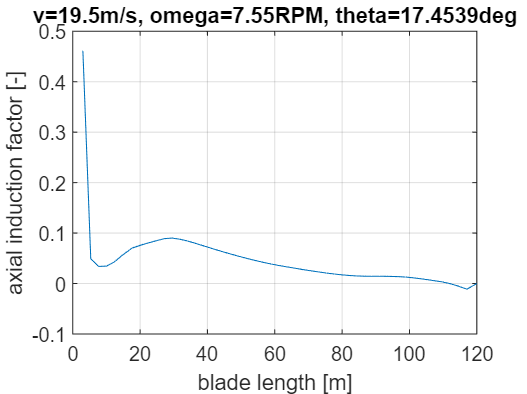

j=34; % steady state point

[THRUST,TANG,BENDING,TORQUE,POWER,a,pn,pt]=...
    BEMexplorer(SS.WINDSPEED(j),SS.ROTSPD(j),SS.BLADEPITCH(j),bladedata);
clf
plot(bladedata.radius,a);
title(['v=' num2str(SS.WINDSPEED(j)) ,'m/s' ', omega=' num2str(SS.ROTSPD(j)) 'RPM' ', theta=' num2str(SS.BLADEPITCH(j)) 'deg'])
grid on
xlabel("blade length [m]")
ylabel("axial induction factor [-]")

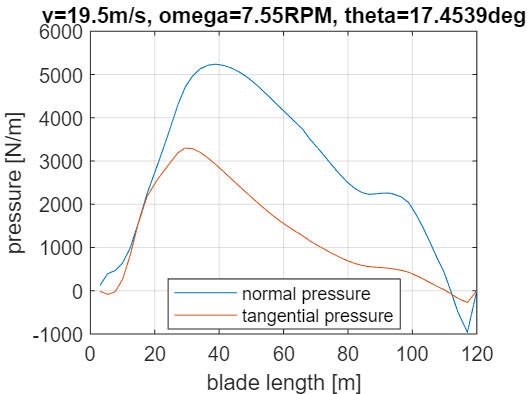


plot(bladedata.radius,pn);
title(['v=' num2str(SS.WINDSPEED(j)) ,'m/s' ', omega=' num2str(SS.ROTSPD(j)) 'RPM' ', theta=' num2str(SS.BLADEPITCH(j)) 'deg'])
grid on
xlabel("blade length [m]")
hold on
plot(bladedata.radius,pt);
ylabel("pressure [N/m]")
legend("normal pressure","tangential pressure",Location="best")
hold off

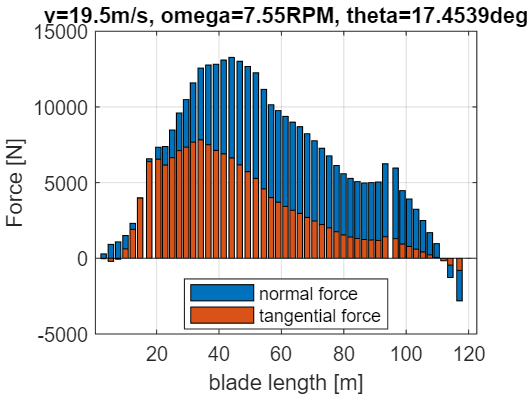

MY=trapz(pn.*bladedata.radius,bladedata.radius);

bar(bladedata.radius,pn.*gradient(bladedata.radius));
title(['v=' num2str(SS.WINDSPEED(j)) ,'m/s' ', omega=' num2str(SS.ROTSPD(j)) 'RPM' ', theta=' num2str(SS.BLADEPITCH(j)) 'deg'])
grid on
xlabel("blade length [m]")
hold on
bar(bladedata.radius,pt.*gradient(bladedata.radius));
ylabel("Force [N]")
legend("normal force","tangential force",Location="best")
hold off

My= sum(pn.*gradient(bladedata.radius))
